clear all; clc;
inletdata=readtable("AS4excel Data","sheet","Inlet");
Aerodata=readtable("AS4excel Data","sheet","Aero");
G=1.4;
R=1715*1.8;
u_Mach=2;
u_alpha=2;
Ac=[2.45 1.95];
u_inlet=2; % inlet=1(4 wedge with 16 isentropic turning)|| inlet=2 (double 2.75 wedge inlet)
U_A_Alt=20000;
U_A_Alpha=u_alpha;
U_A_Mach=u_Mach;
U_N = 6000;
unique_alpha = unique(inletdata.Alpha)';
Inlet1index=find(inletdata.Inlet==1);
Inlet2index=find(inletdata.Inlet==2);
if u_inlet==1
    for counter = 1:5
        if u_alpha<=unique_alpha(counter)
            alpha_u = unique_alpha(counter);
            Ma_1=inletdata.M(find(inletdata.Alpha(Inlet1index)==unique_alpha(counter)));
            Po_1=inletdata.Po2bPoA(find(inletdata.Alpha(Inlet1index)==unique_alpha(counter)));
            Ac_1=inletdata.AabAc(find(inletdata.Alpha(Inlet1index)==unique_alpha(counter)));
            Pu=interp1(Ma_1,Po_1,u_Mach);
            Acu=interp1(Ma_1,Ac_1,u_Mach);
            break
        else
            continue
        end
    end
    for counter = 5:-1:1
        if u_alpha>=unique_alpha(counter)
            alpha_l = unique_alpha(counter);
            Ma_1=inletdata.M(find(inletdata.Alpha(Inlet1index)==unique_alpha(counter)));
            Po_1=inletdata.Po2bPoA(find(inletdata.Alpha(Inlet1index)==unique_alpha(counter)));
            Ac_1=inletdata.AabAc(find(inletdata.Alpha(Inlet1index)==unique_alpha(counter)));
            Pl=interp1(Ma_1,Po_1,u_Mach);
            Acl=interp1(Ma_1,Ac_1,u_Mach);

            break
        else
            continue
        end
    end
else
    for counter = 1:5
        if u_alpha<=unique_alpha(counter)
            alpha_u = unique_alpha(counter);
            Ma_2=inletdata.M(Inlet2index(inletdata.Alpha(Inlet2index)==unique_alpha(counter)));
            Po_2=inletdata.Po2bPoA(Inlet2index(inletdata.Alpha(Inlet2index)==unique_alpha(counter)));
            Ac_2=inletdata.AabAc(Inlet2index(inletdata.Alpha(Inlet2index)==unique_alpha(counter)));
            Pu=interp1(Ma_2,Po_2,u_Mach);
            Acu=interp1(Ma_2,Ac_2,u_Mach);

            break
        else
            continue
        end
    end
    for counter = 5:-1:1
        if u_alpha>=unique_alpha(counter)
            alpha_l = unique_alpha(counter);
            Ma_2=inletdata.M(Inlet2index(inletdata.Alpha(Inlet2index)==unique_alpha(counter)));
            Po_2=inletdata.Po2bPoA(Inlet2index(inletdata.Alpha(Inlet2index)==unique_alpha(counter)));
            Ac_2=inletdata.AabAc(Inlet2index(inletdata.Alpha(Inlet2index)==unique_alpha(counter)));
            Pl=interp1(Ma_2,Po_2,u_Mach);
            Acl=interp1(Ma_2,Ac_2,u_Mach);

            break
        else
            continue
        end
    end
end
P=interp1([alpha_l alpha_u],[Pl Pu], u_alpha);
A_Ac=interp1([alpha_l alpha_u],[Acl Acu], u_alpha);
Cl=zeros(8,8,5);
Cd=zeros(8,8,5);
Q=zeros(8,8,5);
alpha_aero = unique(Aerodata.Alpha)';
Mach_aero = unique(Aerodata.M)';
Alt_aero=unique(Aerodata.Alt)';

for aa=1:length(Alt_aero)
    for bb=1:length(Mach_aero)
        for cc=1:length(alpha_aero)
            Cl(cc,bb,aa)=Aerodata.Cl(Aerodata.Alpha==alpha_aero(cc) & Aerodata.M==Mach_aero(bb) & Aerodata.Alt==Alt_aero(aa));
            Cd(cc,bb,aa)=Aerodata.Cd(Aerodata.Alpha==alpha_aero(cc) & Aerodata.M==Mach_aero(bb) & Aerodata.Alt==Alt_aero(aa));
            q(cc,bb,aa)=Aerodata.Q(Aerodata.Alpha==alpha_aero(cc) & Aerodata.M==Mach_aero(bb) & Aerodata.Alt==Alt_aero(aa));
        end
    end
end
CL=interp3(Mach_aero,alpha_aero,Alt_aero,Cl,U_A_Mach,U_A_Alpha,U_A_Alt);
CD=interp3(Mach_aero,alpha_aero,Alt_aero,Cd,U_A_Mach,U_A_Alpha,U_A_Alt);
Q=interp3(Mach_aero,alpha_aero,Alt_aero,q,U_A_Mach,U_A_Alpha,U_A_Alt);



Tsls=518.69*5/9;
Psls=2116.2;
Pa_values=Psls*[ 0.4599 0.4227 0.3716 0.3404 0.2975 0.2715 0.2360 0.2145 0.1858 0.1534 0.1267 0.1046 0.09507 0.07852 0.07137 0.06486 0.05895 0.05358 0.04871 0.04429 0.01100 ] ;
Ta_values=Tsls*[ 0.8626 0.8489 0.8283 0.8146 0.7940 0.7803 0.7598 0.7519 0.7519 0.7519 0.7519 0.7519 0.7159 0.7519 0.7519 0.7519 0.7519 0.7521 0.7542 0.7563 0.7877 ] ;
Alt= [ 20000 22000 25000 27000 30000 32000 35000 37000 40000 44000 48000 52000 54000 58000 60000 62000 64000 66000 68000 70000 100000];
ALTT=table(Pa_values,Ta_values,Alt);
Ta=interp1(ALTT.Alt,ALTT.Ta_values,U_A_Alt);
Toa=Ta*(1+(G-1)/2*u_Mach^2);
To2=Toa;
thetha=To2/Tsls;
Norm_RPM=U_N/sqrt(thetha);
Norm_RPM_values= [8000 7000 6000 5250 4600 4000];
Norm_Massflow_Values= [0.0575 0.0530 0.0454 0.0340 0.0227 0.0097];
Norm_Thrust_values= [0.294 0.286 0.271 0.247 0.206 0];
P_R_values=[8.17 6.24 4.49 3.42 2.67 2.32];
f_values=[2.992 2.693 2.394 2.094 1.795 1.496];
Engine_data=table(Norm_RPM_values,Norm_Massflow_Values,Norm_Thrust_values,P_R_values,f_values);
Norm_Massflow=interp1(Engine_data.Norm_RPM_values,Engine_data.Norm_Massflow_Values,Norm_RPM)

Norm_Massflow = 0.0264

Norm_Thrust=interp1(Engine_data.Norm_RPM_values,Engine_data.Norm_Thrust_values,Norm_RPM)

Norm_Thrust = 0.2196

P_R=interp1(Engine_data.Norm_RPM_values,Engine_data.P_R_values,Norm_RPM)

P_R = 2.9183

f=interp1(Engine_data.Norm_RPM_values,Engine_data.f_values,Norm_RPM)

f = 1.8940

Inlet1= 2.45; % capture ratio ft^2
Inlet2= 1.95; % capture ratio ft^2
A_As=(((G+1)/2)^-((G+1)/(G-1)/2)) / u_Mach * (1 + u_Mach^2 * (G-1)/2)^((G+1)/(G-1)/2)

A_As = 1.6875

Inlet_Massflow_I1=((sqrt(G/R))*(2/(G+1))^((G+1)/(2*(G-1))))*(1/P)*(1/(A_As))*A_Ac*Ac(u_inlet)

Inlet_Massflow_I1 = 0.0166

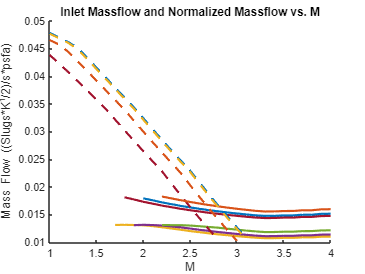

M = [1:0.1:4];
Inlet_Massflow_I1 = zeros(1,length(M));
Norm_Massflow = zeros(1,length(M));
Altitudes = [10000 12000 15000 20000 30000 40000 50000 60000 70000];
figure;
hold on;
alpha=[ 7 11 17];
for ii=1:1:length(alpha)
for k=[1 2]
    for j = 1:length(Altitudes)
    Ta = interp1(ALTT.Alt,ALTT.Ta_values,Altitudes(j));
    for i = 1:length(M)
        [P,A_Ac] = Inletfunction(M(i),alpha(ii),inletdata,k);
        A_As = (((G+1)/2)^-((G+1)/(G-1)/2)) / M(i) * (1 + M(i)^2 * (G-1)/2)^((G+1)/(G-1)/2);
        Inlet_Massflow_I1(i) = ((sqrt(G/R))*(2/(G+1))^((G+1)/(2*(G-1))))*(1/P)*(1./(A_As))*A_Ac*Ac(k);
        Toa = Ta*(1+(G-1)/2*M(i).^2);
        To2 = Toa;
        thetha = To2./Tsls;
        Norm_RPM = U_N./sqrt(thetha);
        Norm_Massflow(i) = interp1(Engine_data.Norm_RPM_values,Engine_data.Norm_Massflow_Values,Norm_RPM);
    end

    plot(M,Inlet_Massflow_I1,'-','LineWidth',2)
    plot(M,Norm_Massflow,'--','LineWidth',2)
    end
end
end
title('Inlet Massflow and Normalized Massflow vs. M')
xlabel('M')
ylabel('Mass Flow ((Slugs*K^1/2)/s*psfa)')

Func= @(x)ThrustFunction(x,u_Mach,inletdata,Engine_data,ALTT,u_inlet,U_A_Alt,Ac,G,R,Norm_Thrust,Mach_aero,alpha_aero,Alt_aero,Cl,Cd,q)

Func = function_handle with value:
    @(x)ThrustFunction(x,u_Mach,inletdata,Engine_data,ALTT,u_inlet,U_A_Alt,Ac,G,R,Norm_Thrust,Mach_aero,alpha_aero,Alt_aero,Cl,Cd,q)

Trimming=fsolve(Func,[2 6000])


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Trimming = 	1.0e+03 *

    0.0013    7.0836


%[A]= ThrustFunction([2,6000],u_Mach,inletdata,Engine_data,ALTT,u_inlet,U_A_Alt,Ac,G,R,Norm_Thrust,Mach_aero,alpha_aero,Alt_aero,Cl,Cd,q)

function [F]= ThrustFunction(x,u_Mach,inletdata,Engine_data,ALTT,u_inlet,U_A_Alt,Ac,G,R,Norm_Thrust,Mach_aero,alpha_aero,Alt_aero,Cl,Cd,q)

u_alpha=x(1);
U_N=x(2);
CL=interp3(Mach_aero,alpha_aero,Alt_aero,Cl,u_Mach,u_alpha,U_A_Alt);
CD=interp3(Mach_aero,alpha_aero,Alt_aero,Cd,u_Mach,u_alpha,U_A_Alt);
Q=interp3(Mach_aero,alpha_aero,Alt_aero,q,u_Mach,u_alpha,U_A_Alt);
Aref=pi()./4*2.5^2;
L=Q*CL*Aref;
D=Q*CD*Aref;
[Po2,A_Ac,Norm_Massflow,To2,OPR]= PressureFunction(u_Mach,u_alpha,U_N,inletdata,Engine_data,ALTT,u_inlet,U_A_Alt,Ac,G,R);
Gh=1.33;
% eta_c=0.95;
% eta_b=0.99;
% QR=4.83*10^8;
% Cp_c=(G.*R)./(G-1);
% Cp_h=(Gh.*R)./(Gh-1);
% To3=To2.*(1+1./eta_c.*(OPR^((G-1)./G)-1));
% To4=(Cp_c.*To3+eta_b.*QR.*f)./(Cp_h.*(1+f));

Aa=A_Ac*Ac(u_inlet);
Ma=Norm_Massflow.*(Po2./sqrt(To2));
T=Norm_Thrust.*Po2.*Aref.*Ma-Q.*Aa;
Tnet=T.*(1-15/100);%thrust penalty 15%

F(1)=real(Tnet.*cosd(u_alpha)-D);
if isnan(F(1))
    F(1)=1;
end
Wfull=2500;
Wemp=2500-800;
F(2)=real(Tnet.*sind(u_alpha)-Wfull+L);
if isnan(F(1))
    F(2)=1;
end
%Fy_emp=Tnet.*sind(u_alpha)-Wemp+L

end